# 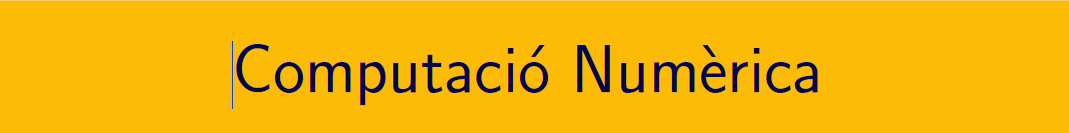

================================================================================

# Pràctica 11. Integració aproximada de funcions i dades (II).

`Document preparat per M. Àngela Grau Gotés - 10 de maig de 2023`

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document .pdf i en el document **CN_exercicis_tema5_2.pdf**, els podeu trobar en el campus virtual. 

### Bloc 4.  Monte Carlo Simulation

Una petita introducció dels mètodes en MATLAB® es pot consultar a l'enllaç següent: [https://es.mathworks.com/discovery/monte-carlo-simulation.html](https://es.mathworks.com/discovery/monte-carlo-simulation.html)

Integració aproximada pel mètode de Montecarlo:  una explicació en el video del professor Craig McNeile a youtube [https://www.youtube.com/watch?v=AaCeUpSFHAk](https://www.youtube.com/watch?v=AaCeUpSFHAk) 

Que s'enten per Monte Carlo Simulation? Una classe del professor John Guttag en el Mit Course: [Introduction to Computational Thinking and Data Science](https://ocw.mit.edu/courses/electrical-engineering-and-computer-science/6-0002-introduction-to-computational-thinking-and-data-science-fall-2016/). Disponible a l'enllaç [https://www.youtube.com/watch?v=OgO1gpXSUzU](https://www.youtube.com/watch?v=OgO1gpXSUzU)

### Bloc 5.  Fórmules d'integració GAUSSIANA

Podeu descarregar els codis de MatLab File Exchange:   

- [Gaussian quadratures for several orthogonal polynomials](https://es.mathworks.com/matlabcentral/fileexchange/48144-gaussian-quadratures-for-several-orthogonal-polynomials) (Chebyshev)

- [Legendre Laguerre and Hermite - Gauss Quadrature](https://es.mathworks.com/matlabcentral/fileexchange/26737-legendre-laguerre-and-hermite-gauss-quadrature?s_tid=prof_contriblnk)

### Integració Gauss-Legendre

La fórmula d'integració és $\displaystyle\int_{-1}^{1} f(x)\,dx=\sum_{j=1}^{m}\beta_i f(x_i)+E_m\{f\}  $ amb els nodes $\mathbf{x_1,\dots,x_m}$ els zeros del polinomi de Legendre de grau $m$ i $\displaystyle  W_j= \displaystyle\int_{-1}^{1} l_j(x)\,dx$ per $l_j(x)$els polinomis interpoladors de Lagrange dels nodes escollits

### Polinomis de Legendre.

    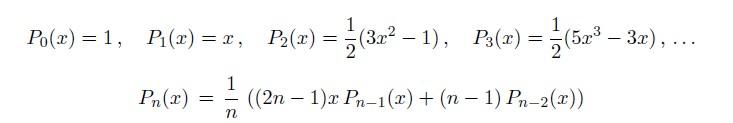

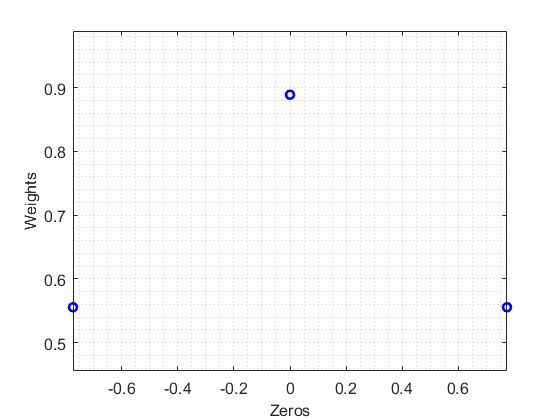

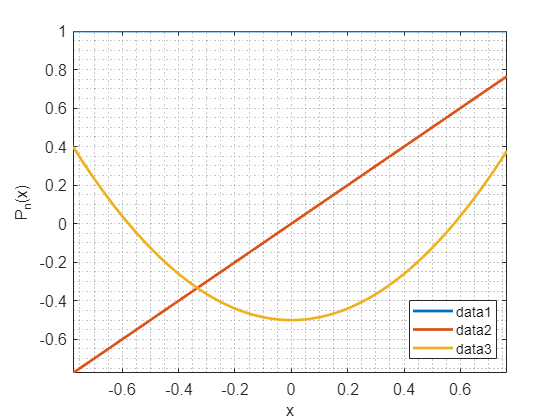

xi =    -0.7746
         0
    0.7746


w =     0.5556
    0.8889
    0.5556


clc,clf,clearvars
m = 3;
[xi, w] = gauss_quad(m,'legen')   % Felipe Uribe, Gaussian quadratures for several orthogonal polynomials 

%[x3, w3] = GaussLegendre_2(m)     % Geert Van Damme, Legendre Laguerre and Hermite - Gauss Quadrature

### Integració Gauss-Legendre

La fórmula d'integració és $\displaystyle
\int_{-1}^{1} \frac{g(t)}{\sqrt{1-t^2}}\,dt=\frac{\pi}{m}\sum_{i=1}^{m} g(t_i)+E_m\{g\}$ amb  els nodes $\mathbf{t_i} = \displaystyle\cos\left[ \frac{(2i-1)\pi}{2m}\right],\  i=1,\cdots,m$ els zeros del polinomi de Txebixev de grau $m$.

### Polinomis de Chebyshev

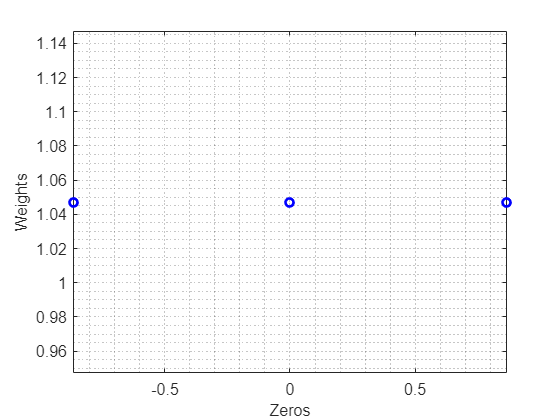

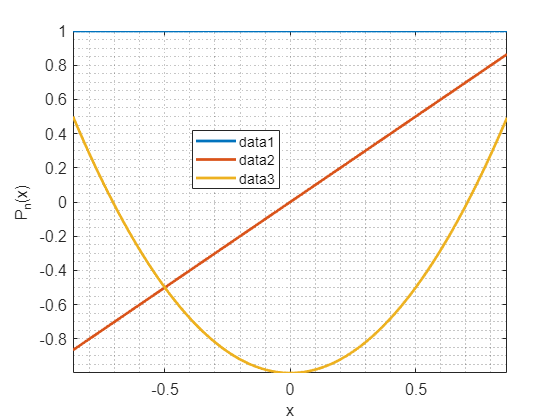

xi =    -0.8660
         0
    0.8660


w =     1.0472
    1.0472
    1.0472


clc,clf,clearvars
m = 3;
[xi,w] = gauss_quad(m,'cheby')

## PRCTIQUEM .....

### Exercici 1. Aplicació dades discretes

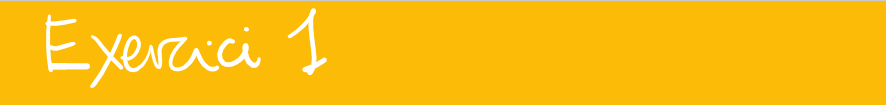

Trobeu la distància que ha recorregut un mòvil a partit de les dades de la següent taula

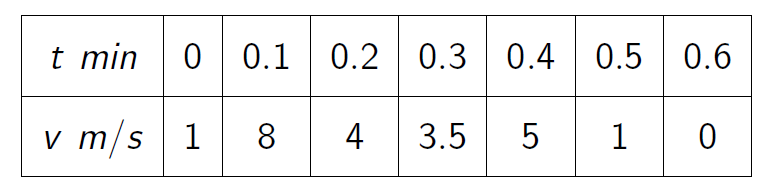

time = linspace(0,0.6,7);
vel = [1 8 4 3.5 5 1 0];
t = time*60;
v = vel;

- Representa gràficament les dades de la taula

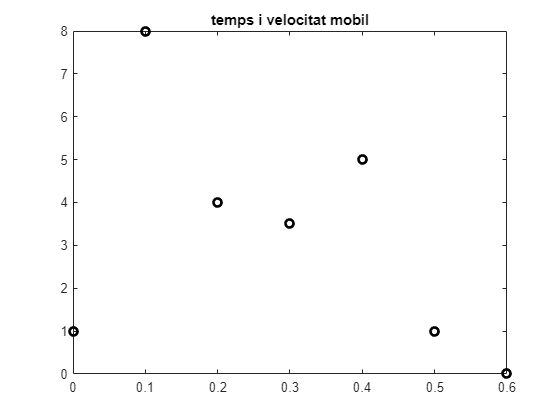

plot(time,vel,'ko', 'LineWidth',2), title('temps i velocitat mobil')

- Explica l'estratègia i dona el resultat pel mètode del punt mig

%dPM = ((t(3) - t(1))*v(2)+(t(5)-t(3))*v(4))

- Explica l'estratègia i dona el resultat pel mètode dels trapezis

dT = trapz(t,v)

dT = 132.0000

cumtrapz(t,v)

ans =          0   27.0000   63.0000   85.5000  111.0000  129.0000  132.0000


- Explica l'estratègia i dona el resultat pel mètode de Simpson

h = (t(3)-t(1))/2;
H = h/3;
dS = H*(v(1)+4*v(2)+v(3))+H*(v(3)+4*v(4)+v(5))+H*(v(5)+4*v(6)+v(7))

dS = 138.0000

### Exercici 2. Mètode de Montecarlo

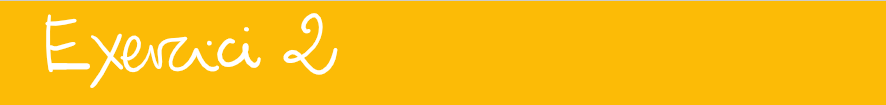

Calculeu els  valors  de    $\displaystyle\int_0^1 x dx = 1/2\,, \quad
\displaystyle\int_0^1 x^2 dx = 1/3\,, \quad
\displaystyle\int_0^4 x dx = 8\,, \quad
\displaystyle\int_{-1}^1 x dx = 0\,.

$

- Tipus I (valor esperat)

%integral 1 - 0: x^2
f = @(x)x.^2;
a = 0; b = 1;
M = 10^6;
idx = (1:M)';
u = rand(M,1);
y = f(u);
if M <= 25
    T = array2table([idx,u,y,cumsum(y)], 'VariableNames',{'k','u','y','sum(y(1:k))'})
    disp(T)
end
valor_aprox = sum(y)/M

valor_aprox = 0.3333

abs(valor_aprox - 1/3)

ans = 3.9011e-05

%integral 4 - 0: x -> canvi a 1 - 0
f = @(x)x;
a = 0; b = 4;
M = 10^4;
idx = (1:M)';
u = a+(b-a)*rand(M,1);
%u = rand(M,1);
y = f(u);
if M <= 25
    T = array2table([idx,u,y,cumsum(y)], 'VariableNames',{'k','u','y','sum(y(1:k))'})
    disp(T)
end
valor_aprox = (b-a)*sum(y)/M

valor_aprox = 7.9178

abs(valor_aprox - 8)

ans = 0.0822

%integral 1 - -1: x -> canvi a 1 - 0
f = @(x)x;
a = -1; b = 1;
M = 10^4;
idx = (1:M)';
u = a+(b-a)*rand(M,1);
%u = rand(M,1);
y = f(u);
if M <= 25
    T = array2table([idx,u,y,cumsum(y)], 'VariableNames',{'k','u','y','sum(y(1:k))'})
    disp(T)
end
valor_aprox = (b-a)*sum(y)/M

valor_aprox = -0.0048

abs(valor_aprox - 0)

ans = 0.0048

- Tipus II (hit or miss)

M = 10^4;
U = rand(M,2);
a = 0; b = 1;
x = a+(b-a)*U(:,1);
y = a+(b-a)*U(:,2);

F = @(x,y)x.^2+y.^2-1

F = function_handle with value:
    @(x,y)x.^2+y.^2-1


v = F(x,y) <= 0;
if M <= 25
    T = array2table([x, y, F(x,y), v], 'VariableNames',{'x','y','x^2+y^2-1', 'v'})
    disp(T)
end
dins = sum(v);
tots = M;
box = 4;
I = dins/tots*box

I = 3.1292

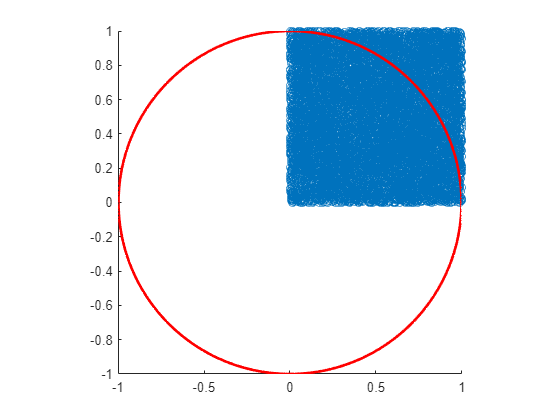

scatter(x, y), hold on
fimplicit(F, 'Color','r','LineWidth',2), daspect([1,1,1]),hold off

### Exercici 3. Mètode de Montecarlo

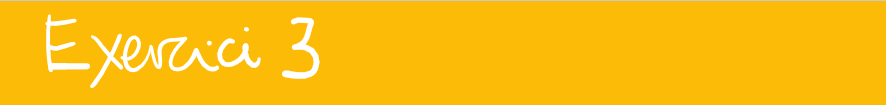

Calculeu el valor de    $\displaystyle \int_{-1}^1 e^\frac{-x^2}{2} dx\ \approx\  { 1.71124878378430\pm 0.510^{-14}}$ 

- Tipus I (valor esperat)

clearvars 
f = @(x)exp((-x.^2)/2);
a = -1; b = 1;
I = 1.71124878378430 

I = 1.7112

M = 10^4;
idx = (1:M)';
u = a+(b-a)*rand(M,1);
%u = rand(M,1);
y = f(u);
if M <= 25
    T = array2table([idx,u,y,cumsum(y)], 'VariableNames',{'k','u','y','sum(y(1:k))'})
    disp(T)
end
valor_aprox = (b-a)*sum(y)/M

valor_aprox = 1.7124

abs(valor_aprox-I)

ans = 0.0012

- Tipus II (hit or miss)

M = 10^2;
U = rand(M,2)

U =     0.6443    0.0596
    0.3786    0.6820
    0.8116    0.0424
    0.5328    0.0714
    0.3507    0.5216
    0.9390    0.0967
    0.8759    0.8181
    0.5502    0.8175
    0.6225    0.7224
    0.5870    0.1499


x = a+(b-a)*U(:,1)

x =     0.2886
   -0.2428
    0.6232
    0.0657
   -0.2985
    0.8780
    0.7519
    0.1003
    0.2450
    0.1741


y = U(:,2)

y =     0.0596
    0.6820
    0.0424
    0.0714
    0.5216
    0.0967
    0.8181
    0.8175
    0.7224
    0.1499



v = y <= f(x);
if M <= 25
    T = array2table([x, y, f(x,y), v], 'VariableNames',{'x','y','x^2+y^2-1', 'v'})
    disp(T)
end
dins = sum(v);
tots = M;
box = (b-a);
I = dins/tots*box

I = 1.7000

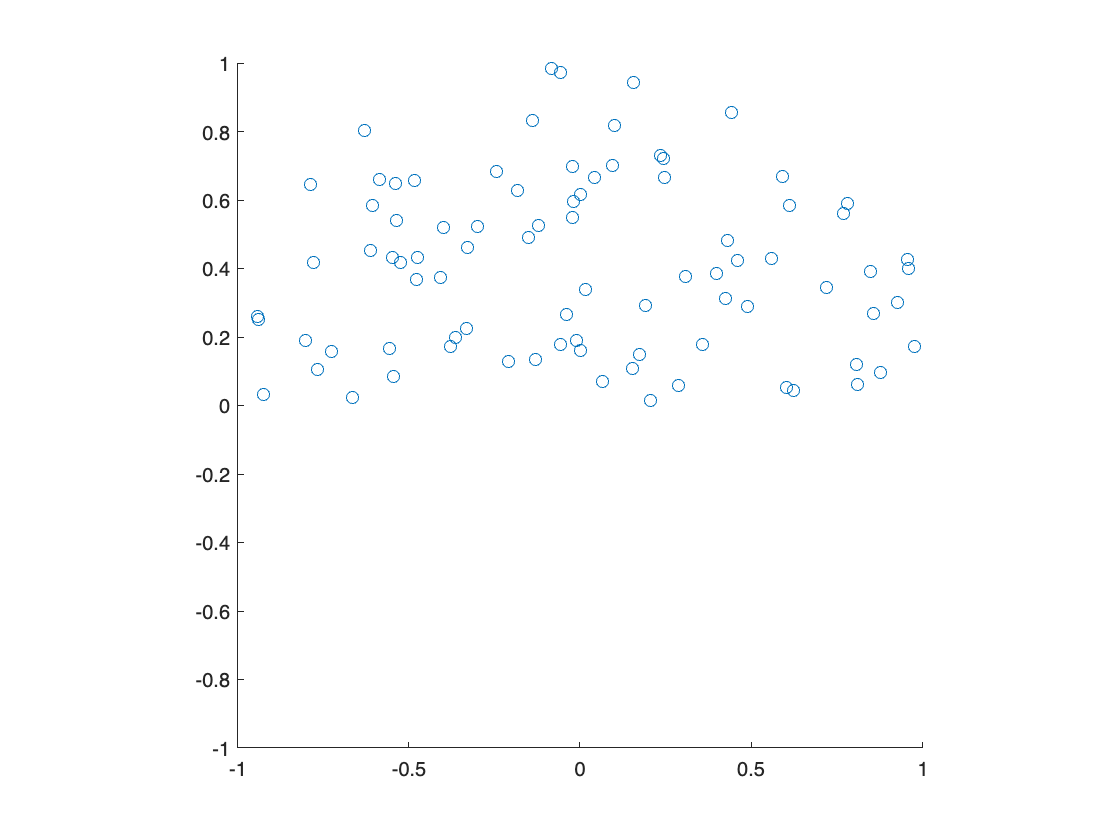

scatter(x(v), y(v)), hold on
fimplicit(f, [-1,1], 'color','r','LineWidth',2), daspect([1,1,1]),hold off

### Exercici 4. Gauss Legendre

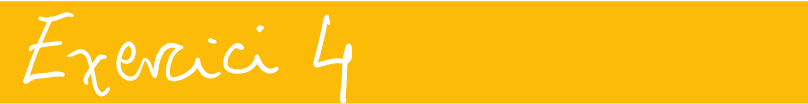

Calcular $\displaystyle \int_{-1}^1 e^\frac{-x^2}{2} dx\ \approx\  { 1.71124878378430\pm 0.510^{-14}}$

- Valor exacte

clearvars
Ie = 1.711

Ie =                      1.711


f = @(x)exp((-x.^2)/2);

- Fórmula de dos punts: m=2

format long g
m = 2

m =      2


[x, w] = GaussLegendre(m)

x =         -0.577350269189626
         0.577350269189626


w =                          1
                         1


GL2 = sum(w.*f(x))

GL2 =           1.69296344978123


Gerror = abs(GL2-Ie)

Gerror =         0.0180365502187725


- Fórmula de tres punts: m=3

m = 3

m =      3


[x, w] = GaussLegendre(m);
GL2 = sum(w.*f(x))

GL2 =           1.71202024520191


Gerror = abs(GL2-Ie)

Gerror =        0.00102024520190835


- Fórmula de quatre punts: m=4

- Fórmula de cinc punts: m=5

### Exercici 5. Gauss Chebyshev

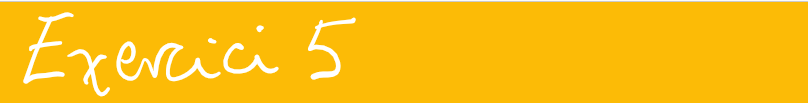

Calculeu el valor de    $$\quad\displaystyle  \int_{-1}^{1}\frac{\cos(\pi x)}{\sqrt{1-x^2}}dx $$ 

- Valor exacte

clc; clear variables; format compact;
format longG;
a = -1; b = 1;
g = @(x)cos(pi.*x);
%f = @(x)cos(pi*x)/sqrt(1-x^2)

- Fórmula de dos punts: m=2. Compareu el valor calculat per trapezis (1interval=dos punts)

m = 2

m =      2

[x, w] = GaussTxebixev_2(m)

x =          0.707106781186548        -0.707106781186547


w =            1.5707963267949           1.5707963267949


GTm = sum(w.*g(x))

GTm =          -1.90286225269511

%Gerror = abs(GL2-Ie)
R1 = (b-a)/2*cos(-pi*0.5)/sqrt(1-0.5^2)+(1-0)/2*cos(pi*0-5)/sqrt(1-0.5^2) %2 punts

R1 =          0.163772439136111

- Fórmula de tres punts: m=3.  Compareu el valor calculat per Simpson (1interval=tres punts)

- Fórmula de quatre punts: m=4

- Fórmula de cinc punts: m=5

### Exercici 6. Canvi interval

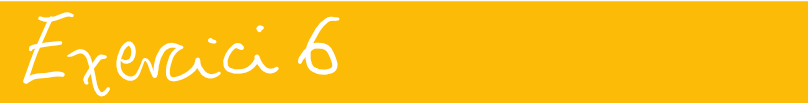

 Calculeu el valor de $  I=\displaystyle\int_{1}^{2} \ln(x)\,dx $ fent ús de fórmules de Gauss-Legendre. Obseveu que el canvi d'interval és $  I=\displaystyle\int_{1}^{2} \ln(x)\,dx = \frac{1}{2}\int_{-1}^{1} \ln\Big(\frac{t+3}{2}\Big)\,dt \,.$

% canvi d'interval a 1 -1 3/2 + t/2 -> t+3/2
g = @(x)log(x)

g = function_handle with value:
    @(x)log(x)


[t, w] = GaussLegendre(2)

t =         -0.577350269189626
         0.577350269189626


w =                          1
                         1


x = (3+t)/2, W = w/2

x =           1.21132486540519
          1.78867513459481


W =                        0.5
                       0.5


GL2 = sum(W.*g(x))

GL2 =          0.386594944116741


## AUTOAVALUACIÓ ....

#### Fórmules de Newton-Côtes compostes. Mètode Romberg.

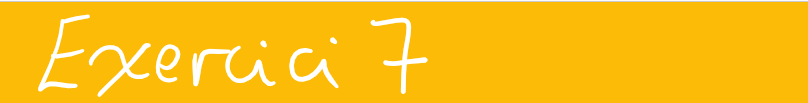

Bajarse el código de [romberg.m](http://www.math.mcgill.ca/gantumur/math578f09/matlab/romberg.m)

            
$$\displaystyle \int_{-1}^1 e^\frac{-x^2}{2} dx\ \approx\  { 1.71124878378430\pm 0.510^{-14}}$$


- Valor exacte

clearvars
format shortG
a=-1; b=1; 
f = @(x)exp(-x.^2/2);

- Mètode del punt mig, h=1,1/2,1/4,1/8,1/16. Exercici per verificar que P(h), P(h/2) ...  millora l'aproximació

- Mètode dels trapezis, h=1,1/2,1/4,1/8,1/16. Exercici per verificar que T(h), T(h/2) ...  millora l'aproximació

- Regla de Simpson, h=1,1/2,1/4,1/8. Exercici per verificar que S(h), S(h/2) ...  millora l'aproximació

- Mètode de Romberg, h=1,1/2,1/4,1/8,1/16

- Fórmula de Gauss-Legendre dos punts: m=2. Compareu el valor calculat per trapezis (1interval=dos punts)

- Fórmula de Gauss-Legendre de tres punts: m=3.  Compareu el valor calculat per Simpson (1interval=tres punts)

- Fórmula de Gauss-Legendre de quatre punts: m=4

- Fórmula de Gauss-Legendre de cinc punts: m=5

`Document preparat per M. Àngela Grau Gotés - 10 de maig de 2023`

% Codis de les funcions 

function y = fun(x)
    y = sin(x)./x;
    if isnan(y)
        y = 1;
    end
end

function [x, w] = GaussTxebixev_2(n)
    w = pi/n.*ones(1,n);
    k = 1:n;
    x = cos((2.*k-1).*pi./(2*n));
end